## Pan step response - Real system test

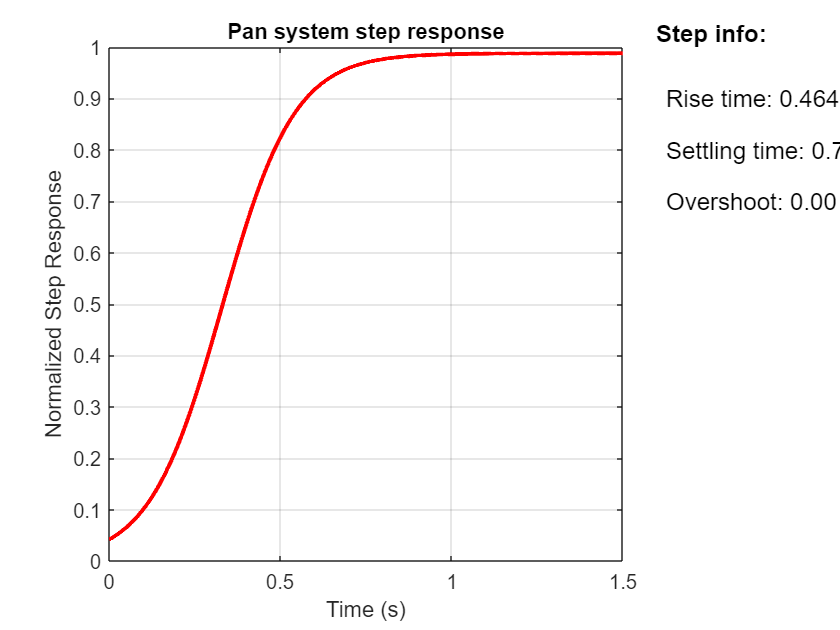

clear 
clc

% Loading and preping data from raw_pan_values
error = load('raw_pan_values.txt');
Fs = 1000; Ts = 1/Fs;
n = min(length(error), 1500);
t = (0:n-1)' * Ts;  % Column vector
y = 1 - abs(error(1:n)) / max(abs(error));  % Also a column vector

% Sigmoid fit model
sigmoid = @(b, t) b(1) ./ (1 + exp(-b(2)*(t - b(3))));
b0 = [1, 10, 0.2];  % Initial guess for [L, k, t0]
opts = optimset('Display', 'off');
b_fit = lsqcurvefit(sigmoid, b0, t, y, [], [], opts);
y_fit = sigmoid(b_fit, t);

%%% Setting up figure %%%
figure;
hold on
% LEFT: Sigmoid fitted model for step response
subplot(1,5,[1 4]);
% plot(t, y, 'b', 'LineWidth', 2); hold on; % Plot from raw data
plot(t, y_fit, 'r', 'LineWidth', 2), grid on;    % Sigmoid fitted model for step response
xlabel('Time (s)');
ylabel('Normalized Step Response');
title('Pan system step response');
% RIGHT: Step info from fitted sigmoid model
subplot(1,5,5);
info_pan = stepinfo(y_fit, t, 'RiseTimeLimits', [0.1 0.9]);
set(title('Step info:', 'FontSize', 12), 'Units', 'normalized', 'Position', [0 1 0], 'HorizontalAlignment', 'left');
axis off; % Hide axes
text(0.1, 0.9, sprintf('Rise time: %.3f s', info_pan.RiseTime), 'FontSize', 12);
text(0.1, 0.8, sprintf('Settling time: %.3f s', info_pan.SettlingTime), 'FontSize', 12);
text(0.1, 0.7, sprintf('Overshoot: %.2f %%', info_pan.Overshoot), 'FontSize', 12);
hold off